Open the Data File

clear all
path = 'Z:\My Documents\PMUCal\Output\'

path = 'Z:\My Documents\PMUCal\Output\'

name = 'SavedFit.mat'

name = 'SavedFit.mat'

name = strcat(path,name);
A = open(name);
P = A.P;
clear A;

Get the samples in the row of interest

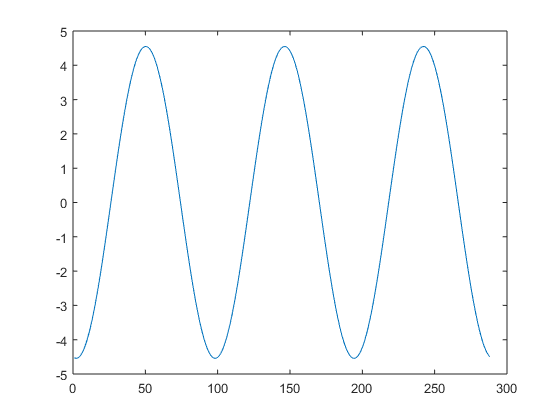

i = 7;
SignalParams = P(i).SignalParams;
DelayCorr = P(i).DelayCorr;
MagCorr = P(i).MagCorr;
F0 = P(i).F0;
AnalysisCycles = P(i).AnalysisCycles;
SampleRate = P(i).SampleRate;
Samples = P(i).Samples;
plot(Samples(1,:))

Run the Steady State Fitter

    [Synx,Freq,ROCOF] = SteadyStateFit ( ...
        SignalParams, ...
        DelayCorr, ...
        MagCorr, ...
        F0, ...
        AnalysisCycles, ...
        SampleRate, ...
        Samples ...
        )

Synx =   67.1369 - 7.7325i -40.2366 -53.9672i -29.0945 +64.8070i  68.2213 - 7.6006i  -0.0000 - 0.0001i   0.0001 - 0.0001i  -0.0006 + 0.0001i   0.0001 + 0.0002i


Freq = 49.9970

ROCOF = -0.0030